读取所有数据，经过DDC与LPF后拼接至ref与sur

ref和sur中包含了[0, 10]s的所有完整数据，是为了方便task3的滑动窗口的计算

如果仅考虑task2计算，则无需拼接，只要在计算每个时间区间时读取对应数据即可

clc, clear,close all;

ref = zeros(1, 250000000);
sur = zeros(1, 250000000);
load(sprintf('data/data_%d.mat',1));

% 设计低通滤波器
[b, a] = butter(20, 9*10^6/(f_s/2),'low');

% 读取所有的文件，将下面改成for idx = 1:20
for idx = 1:20
    left = (idx - 1) * (12500000) + 1;
    right = idx * 12500000;
    load(sprintf('data/data_%d.mat',idx));

    % 频移（DDC）
    f_ddc=3e6;
    ref_shift=seq_ref.*exp(1i*2*pi*f_ddc*(0:1:length(seq_ref)-1)/f_s);
    sur_shift=seq_sur.*exp(1i*2*pi*f_ddc*(0:1:length(seq_sur)-1)/f_s);

    % 低通滤波（LPF）
    ref_filter = filter(b,a,ref_shift);
    sur_filter = filter(b,a,sur_shift);

    ref(left:right) = ref_filter;
    sur(left:right) = sur_filter;
end

对每个区间进行计算

t_interval = 0.5;
t0s = 0:0.1:9.5; % 取t0 = [0.0, 2.0, 5.0, 7.0]进行计算并绘图（实际上，imgs文件夹中保存了所有时间区间的图像）
for t0 = t0s
    t0
    ext_ref = ref(t0 * f_s + 1 : (t0 + t_interval) * f_s);
    ext_sur = sur(t0 * f_s + 1 : (t0 + t_interval) * f_s);
    
    % 取ref共轭
    ext_ref_conj = conj(ext_ref);
    
    % 结果保存在cors中
    cors = zeros(7, 41);
    cors_max = 0;
    max_fd = -1;
    max_tau = -1;
    
    N = length(ext_sur);

计算模糊函数

    tic
    % tau = kTs
    for k = 0 : 6
        ext_ref_conj_shift = [zeros(1, k), ext_ref_conj(1:N-k)];
        n = 1:N;
        for fd = -40:2:40
            e = exp(-1i * 2 * pi * fd/f_s .* (n - 1));
            cor = sum(ext_sur(n) .* ext_ref_conj_shift .* e);
            cor = abs(cor);
            cors(k + 1, (fd + 40) / 2 + 1) = cor;
            % 记录最大值
            if (cor > cors_max) 
                cors_max = cor;
                max_fd = fd;
                max_tau = k;
            end
        end
    end
    toc

画图并保存

    range = 0:12:72;
    freqd = -40:2:40;
    [F,R]=meshgrid(freqd,range);
    surf(F,R,cors / cors_max);
    view(0,90);
    ylim([0 72]);
    xlim([-40 40]);
    xlabel("f_{d}(Hz)");
    ylabel("Range(m)");
    title("t0: " + t0 + "s,    range: " + max_tau * 12 + "m,    f_{d}: " + max_fd + "Hz");
    colorbar
    filename = "imgs_Quicker1/Range-Doppler" + (t0 / 0.1 + 1) + ".png";
    saveas(gcf, filename, 'png');

保存数据

t0 = 0

历时 69.054023 秒。


t0 = 0.1000

历时 67.980587 秒。


t0 = 0.2000

历时 68.050399 秒。


t0 = 0.3000

历时 65.786091 秒。


t0 = 0.4000

历时 64.204771 秒。


t0 = 0.5000

历时 65.660889 秒。


t0 = 0.6000

历时 65.272954 秒。


t0 = 0.7000

历时 64.681824 秒。


t0 = 0.8000

历时 64.386597 秒。


t0 = 0.9000

历时 65.464048 秒。


t0 = 1

历时 64.853167 秒。


t0 = 1.1000

历时 64.465666 秒。


t0 = 1.2000

历时 62.261506 秒。


t0 = 1.3000

历时 62.642423 秒。


t0 = 1.4000

历时 62.165986 秒。


t0 = 1.5000

历时 62.423818 秒。


t0 = 1.6000

历时 62.608067 秒。


t0 = 1.7000

历时 62.048273 秒。


t0 = 1.8000

历时 62.753645 秒。


t0 = 1.9000

历时 65.432592 秒。


t0 = 2

历时 63.850049 秒。


t0 = 2.1000

历时 62.099992 秒。


t0 = 2.2000

历时 62.060714 秒。


t0 = 2.3000

历时 63.159362 秒。


t0 = 2.4000

历时 63.886563 秒。


t0 = 2.5000

历时 61.768913 秒。


t0 = 2.6000

历时 61.778486 秒。


t0 = 2.7000

历时 61.646346 秒。


t0 = 2.8000

历时 61.652992 秒。


t0 = 2.9000

历时 61.788266 秒。


t0 = 3

历时 55.055801 秒。


t0 = 3.1000

历时 62.334168 秒。


t0 = 3.2000

历时 61.572488 秒。


t0 = 3.3000

历时 61.701888 秒。


t0 = 3.4000

历时 61.655325 秒。


t0 = 3.5000

历时 63.749256 秒。


t0 = 3.6000

历时 65.618621 秒。


t0 = 3.7000

历时 67.406195 秒。


t0 = 3.8000

历时 65.505048 秒。


t0 = 3.9000

历时 62.516666 秒。


t0 = 4

历时 62.191925 秒。


t0 = 4.1000

历时 62.897869 秒。


t0 = 4.2000

历时 63.527655 秒。


t0 = 4.3000

历时 63.242439 秒。


t0 = 4.4000

历时 63.770904 秒。


t0 = 4.5000

历时 64.666952 秒。


t0 = 4.6000

历时 62.408670 秒。


t0 = 4.7000

历时 62.034946 秒。


t0 = 4.8000

历时 62.364405 秒。


t0 = 4.9000

历时 63.109928 秒。


t0 = 5

历时 64.348412 秒。


t0 = 5.1000

历时 62.145808 秒。


t0 = 5.2000

历时 63.250042 秒。


t0 = 5.3000

历时 61.892856 秒。


t0 = 5.4000

历时 64.885869 秒。


t0 = 5.5000

历时 62.754709 秒。


t0 = 5.6000

历时 63.305141 秒。


t0 = 5.7000

历时 62.611253 秒。


t0 = 5.8000

历时 62.236932 秒。


t0 = 5.9000

历时 62.091772 秒。


t0 = 6

历时 62.442810 秒。


t0 = 6.1000

历时 62.165450 秒。


t0 = 6.2000

历时 64.012111 秒。


t0 = 6.3000

历时 63.747517 秒。


t0 = 6.4000

历时 62.619561 秒。


t0 = 6.5000

历时 63.849405 秒。


t0 = 6.6000

历时 63.578759 秒。


t0 = 6.7000

历时 62.347763 秒。


t0 = 6.8000

历时 61.787719 秒。


t0 = 6.9000

历时 61.775492 秒。


t0 = 7

历时 61.693222 秒。


t0 = 7.1000

历时 62.339556 秒。


t0 = 7.2000

历时 57.164914 秒。


t0 = 7.3000

历时 55.964102 秒。


t0 = 7.4000

历时 55.898151 秒。


t0 = 7.5000

历时 55.974071 秒。


t0 = 7.6000

历时 56.068623 秒。


t0 = 7.7000

历时 55.886620 秒。


t0 = 7.8000

历时 56.435340 秒。


t0 = 7.9000

历时 55.803005 秒。


t0 = 8

历时 55.768915 秒。


t0 = 8.1000

历时 55.886665 秒。


t0 = 8.2000

历时 55.956203 秒。


t0 = 8.3000

历时 55.973531 秒。


t0 = 8.4000

历时 55.856004 秒。


t0 = 8.5000

历时 62.022580 秒。


t0 = 8.6000

历时 56.195890 秒。


t0 = 8.7000

历时 56.747334 秒。


t0 = 8.8000

历时 56.005222 秒。


t0 = 8.9000

历时 56.848227 秒。


t0 = 9

历时 56.056691 秒。


t0 = 9.1000

历时 56.108609 秒。


t0 = 9.2000

历时 56.184476 秒。


t0 = 9.3000

历时 56.736076 秒。


t0 = 9.4000

历时 56.161175 秒。


t0 = 9.5000

历时 55.799895 秒。


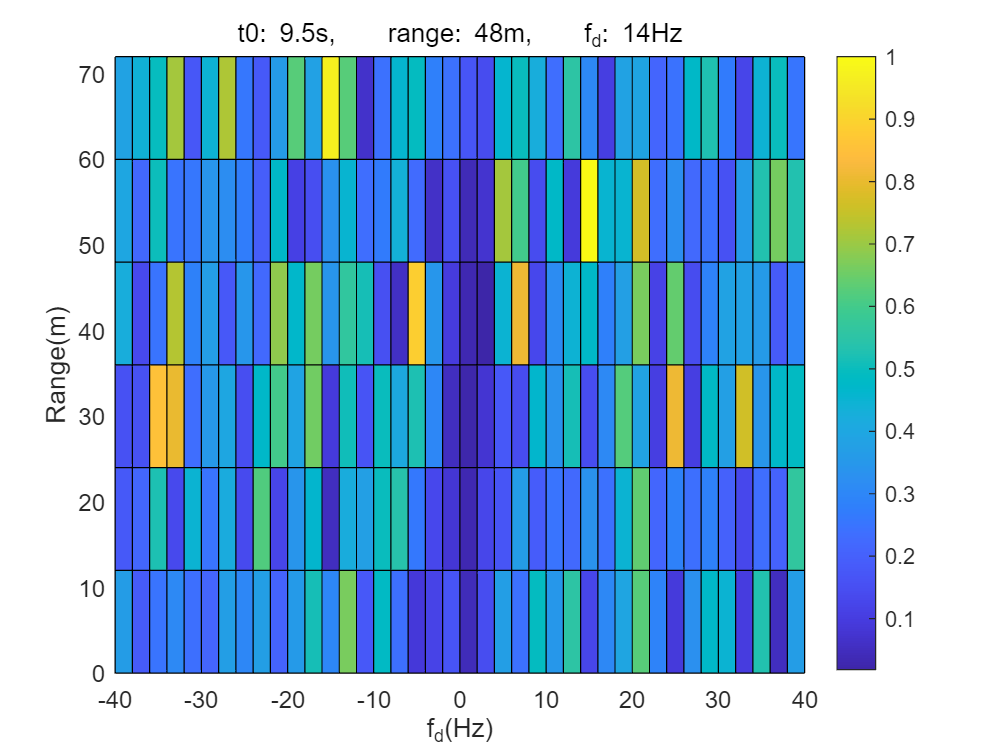

    save("cors/cors" + (t0 / 0.1 + 1) + ".mat", "cors");
end